# **System 2 : Rössler-Attraktor**

Das System von drei gekoppelten Differentialgleichungen lautet:


$$\dot X = - (Y+Z)$$



$$\dot Y = X+aY$$



$$\dot Z = b+(X-c)Z$$


Parameterset 1 : mit a=0,15, b=0,20,c=10,00

Parameterset 2 : mit a=0,20, b=0,20,c=8,00

Wie beeinflussen die einzelnen Parameterden Attraktor?

## `Erweiterung:`

Parameterset 1: a = 0.15;  b = 0.2;  c = 5.7;

 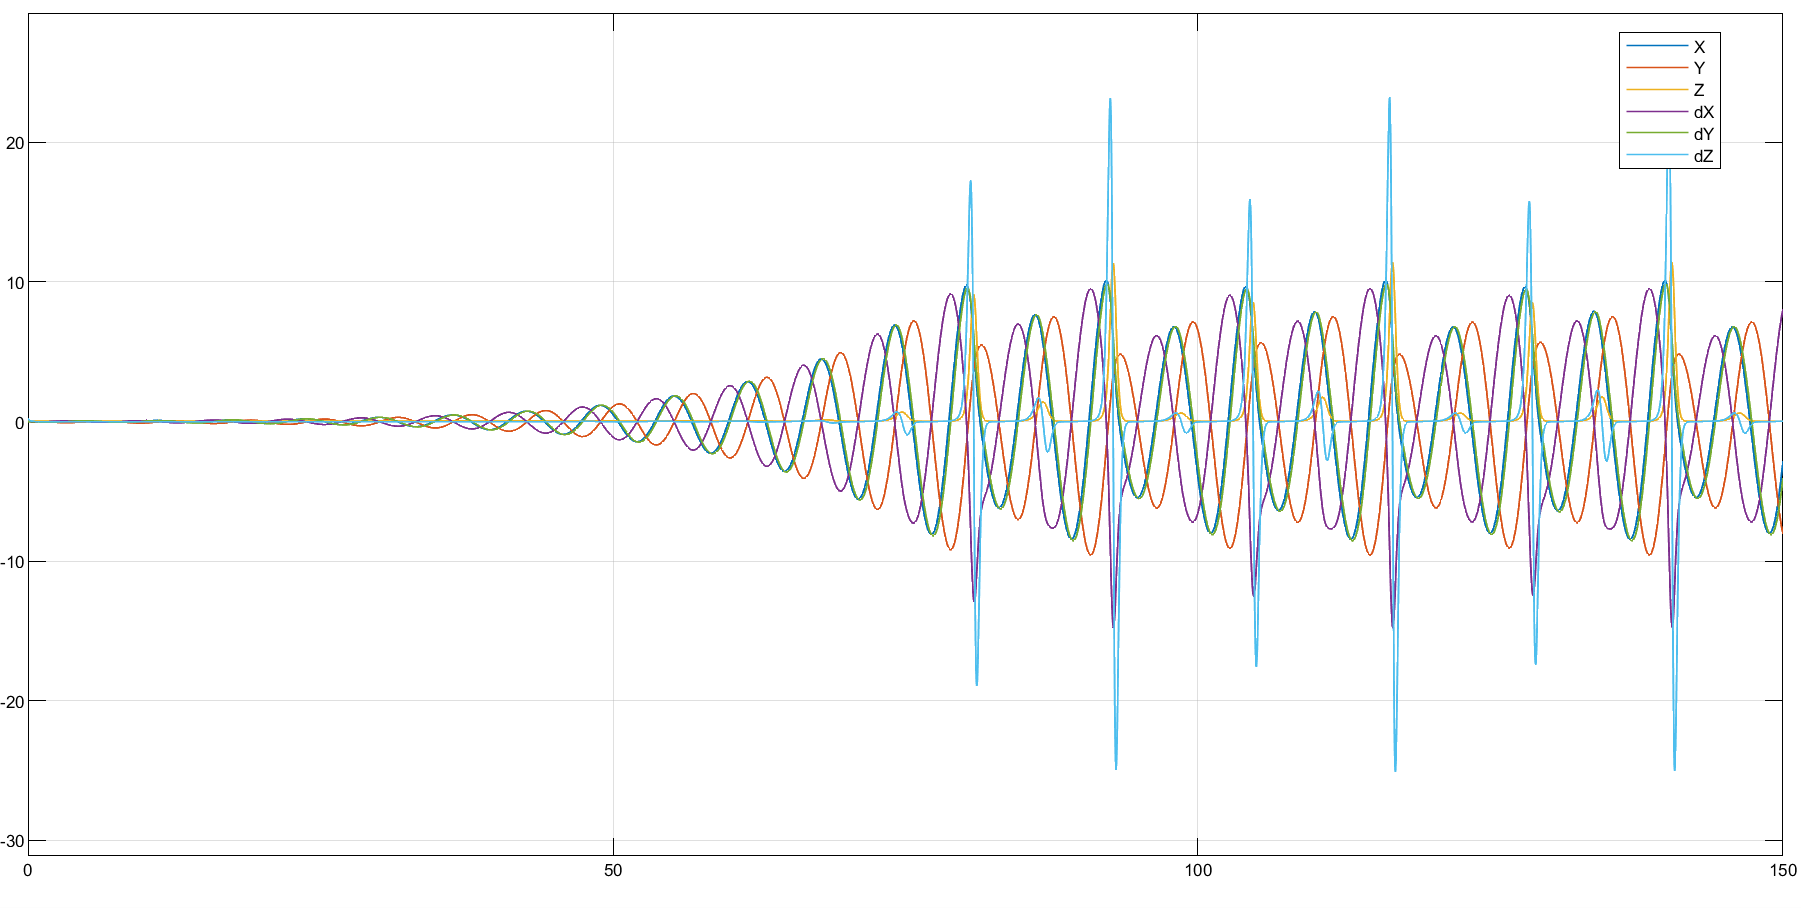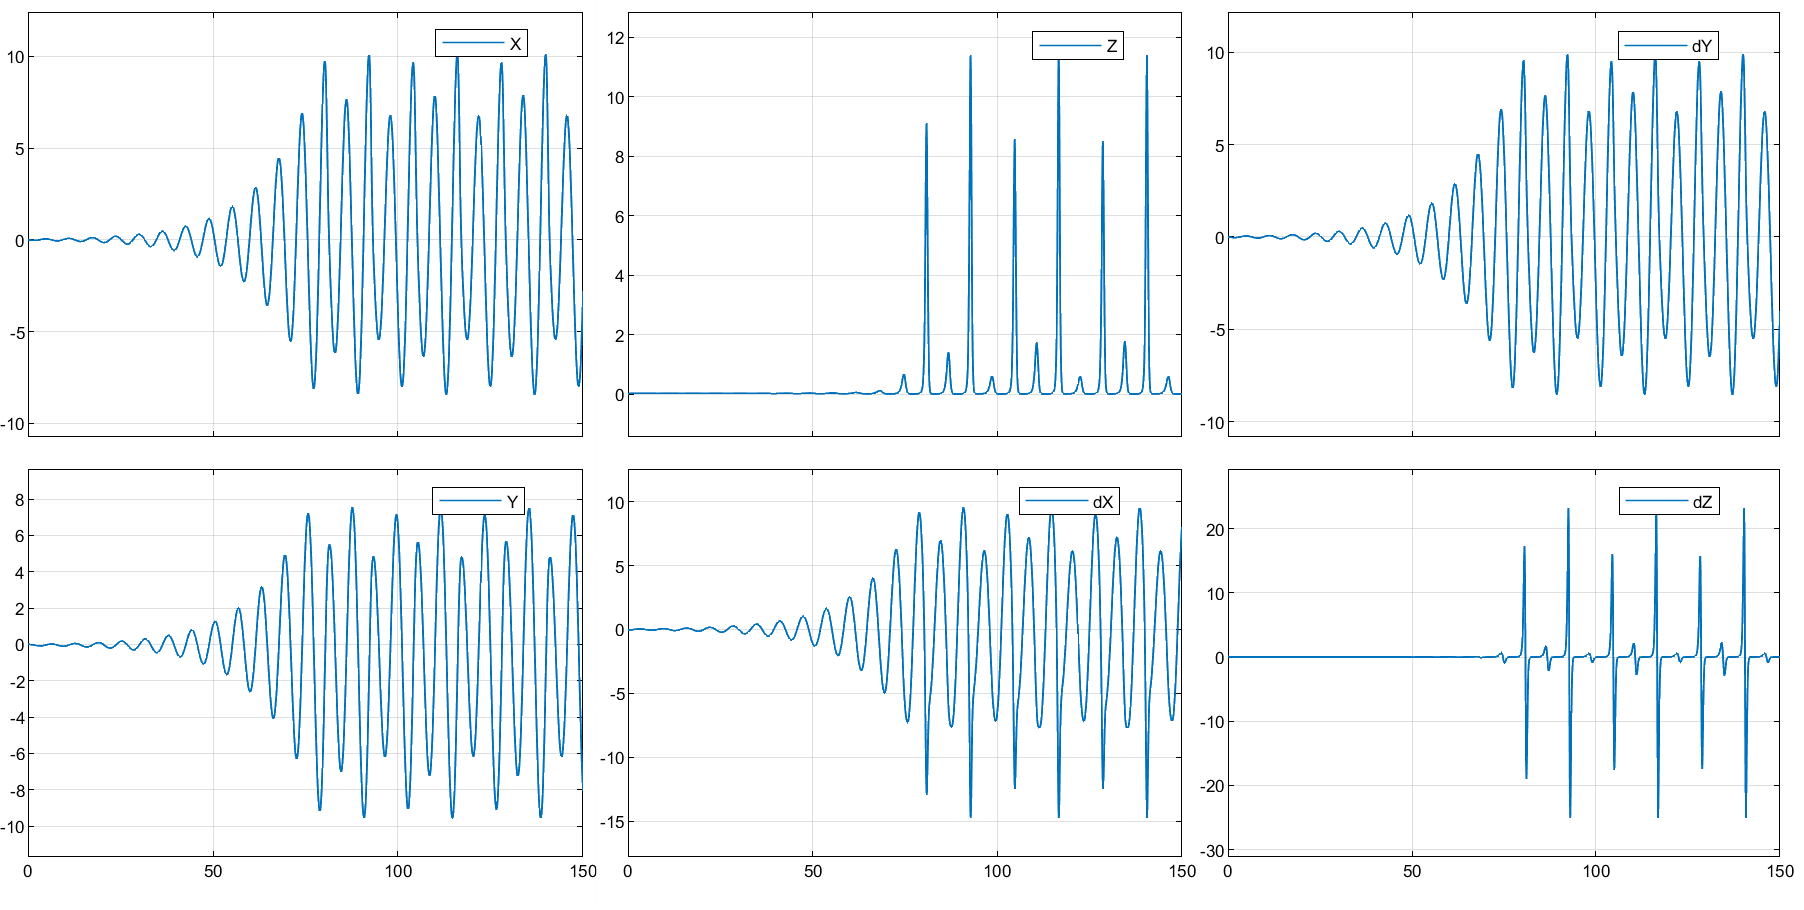

Parameterset 2: ***a = 0.33***;  b = 0.2;  c = 5.7;

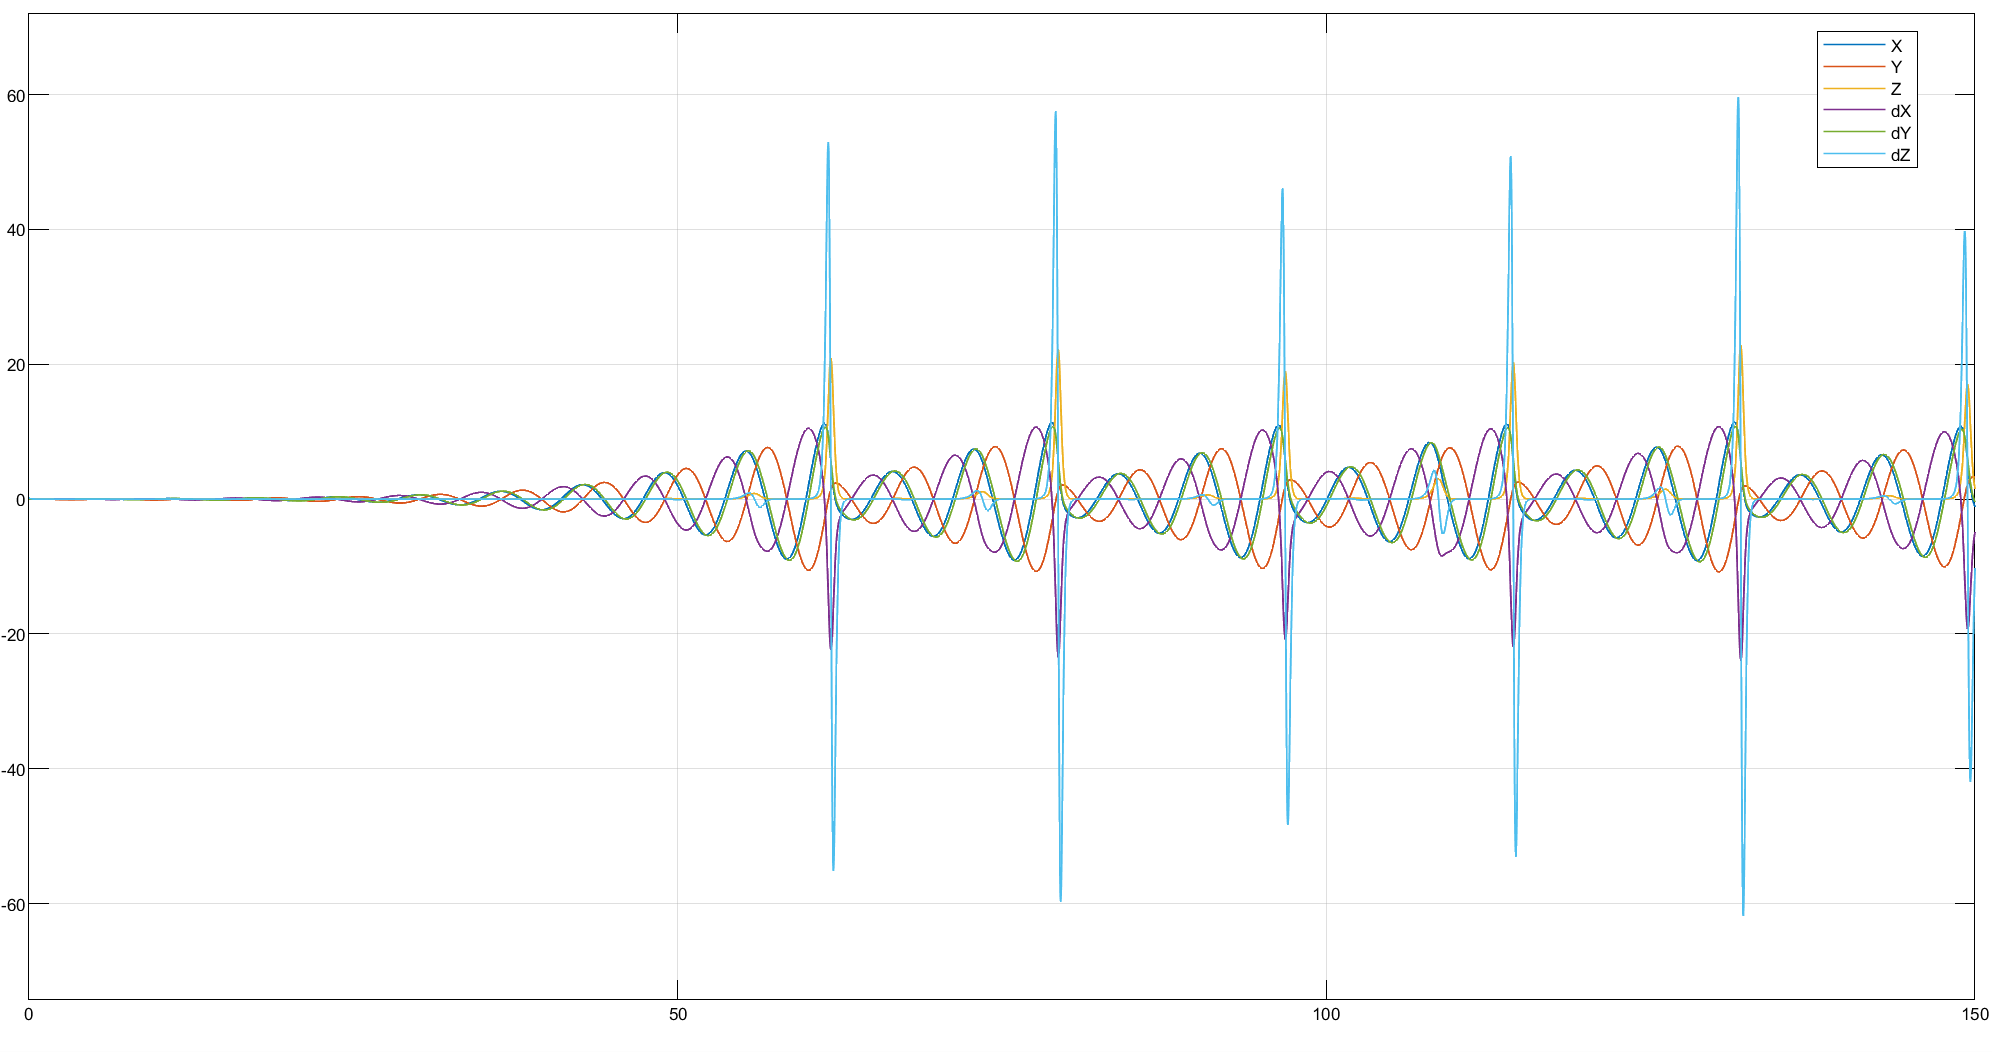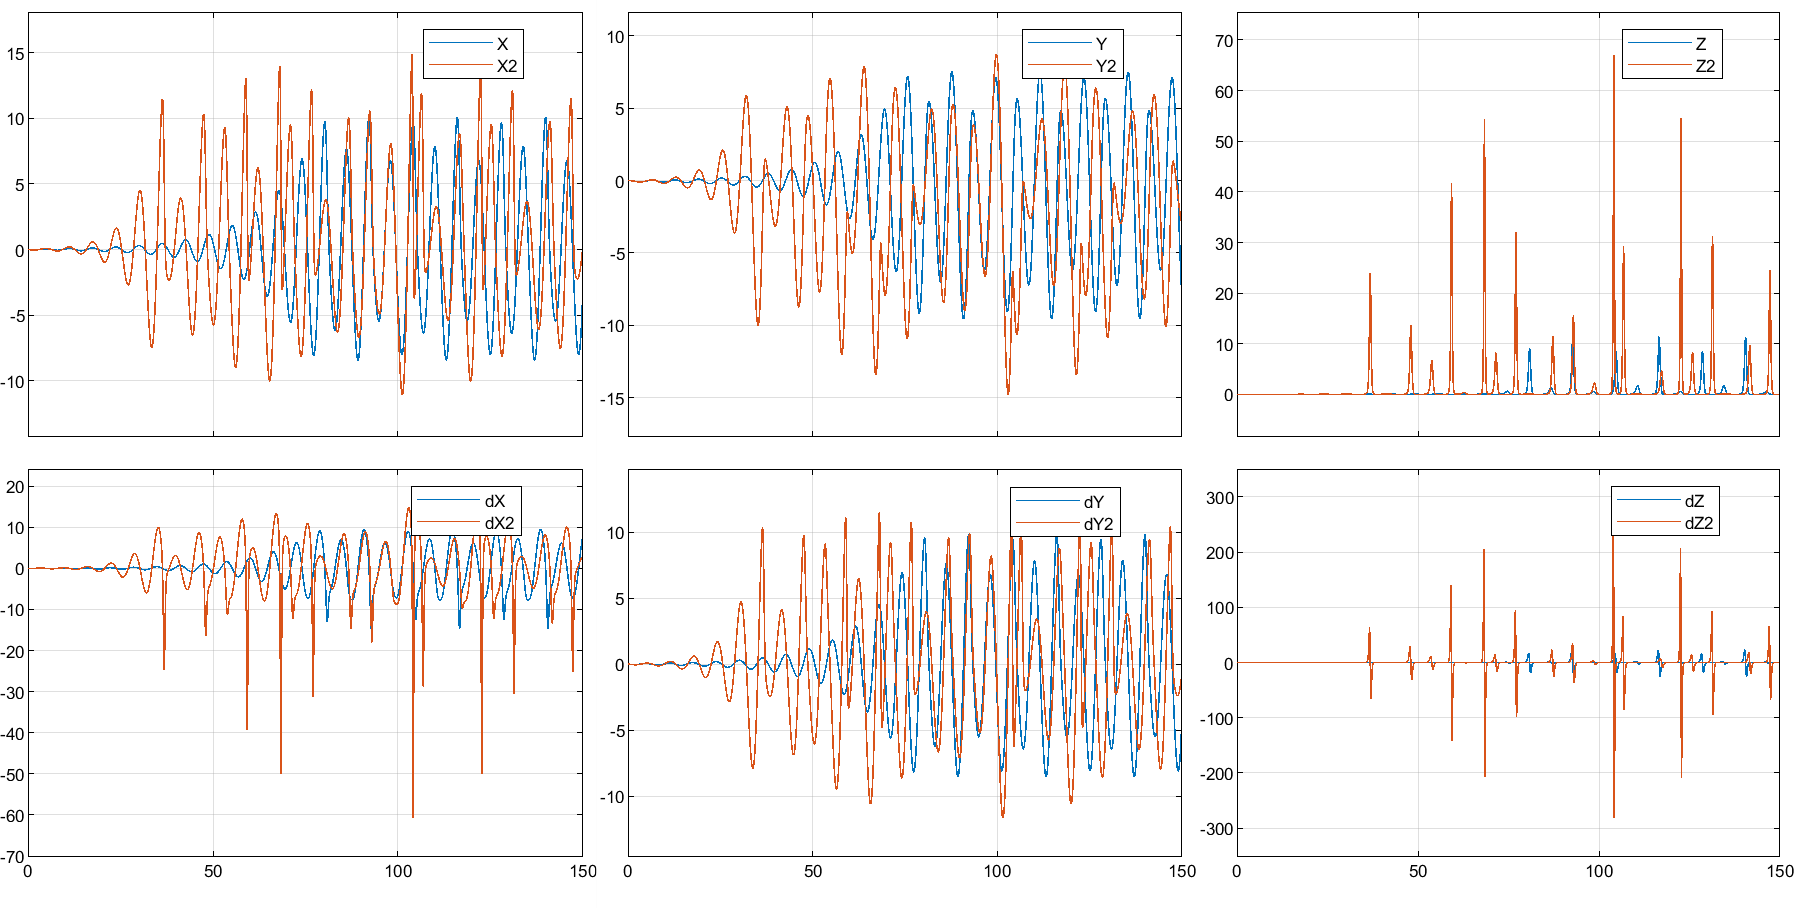

%Parameterset 3: a = 0.15; *** b = 1***;  c = 5.7;

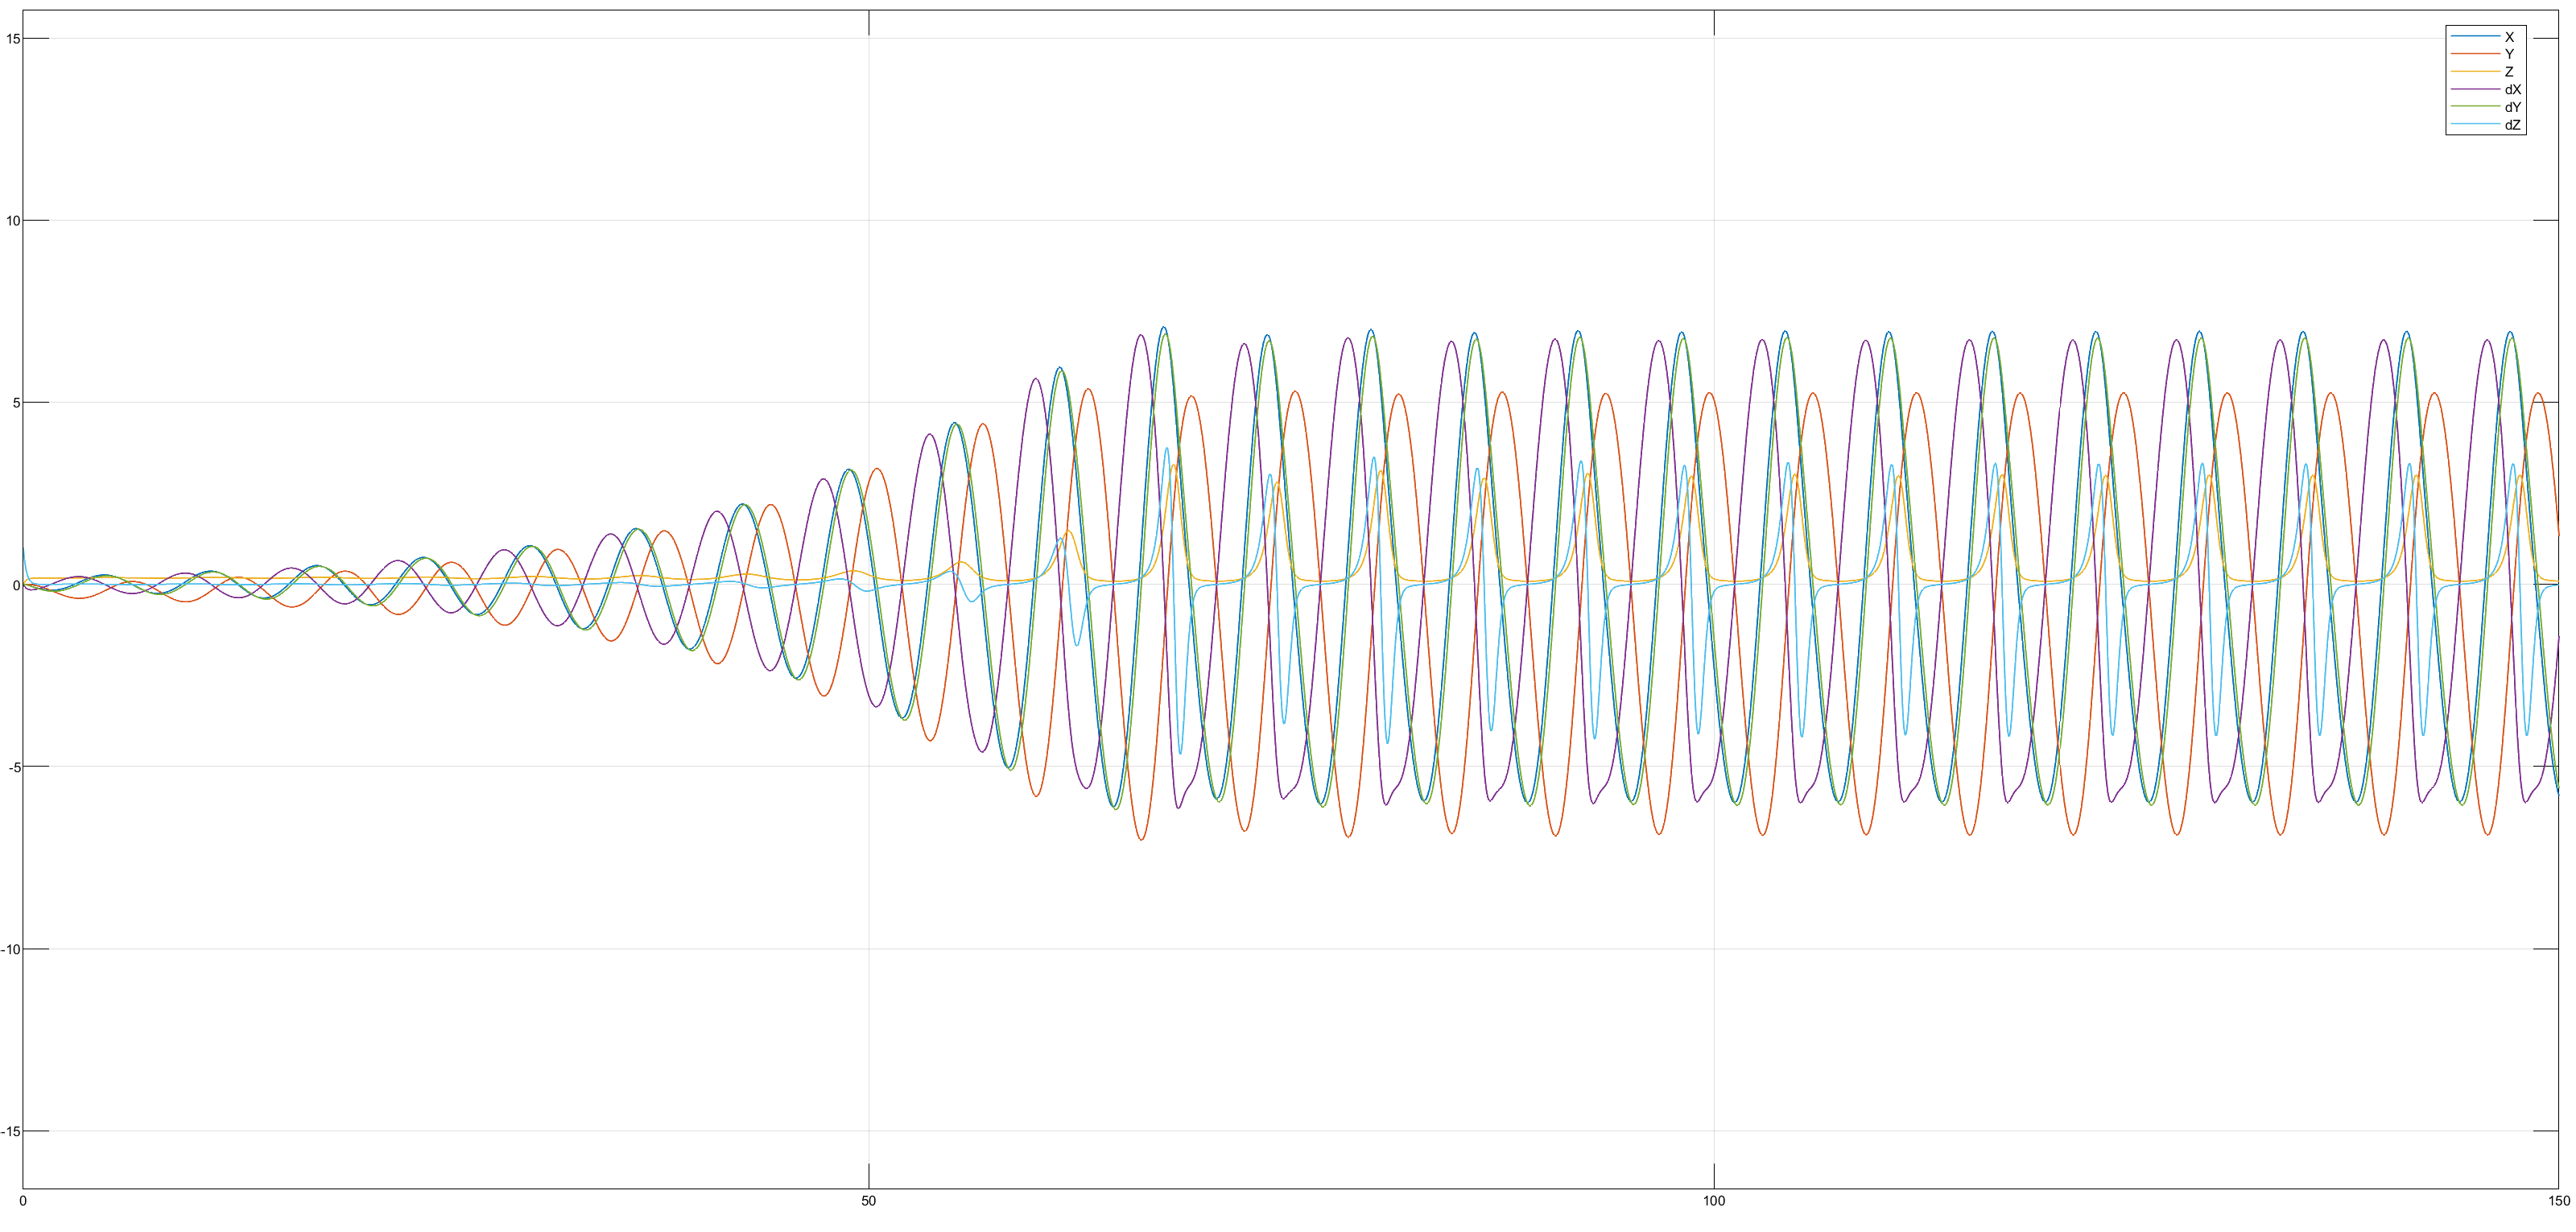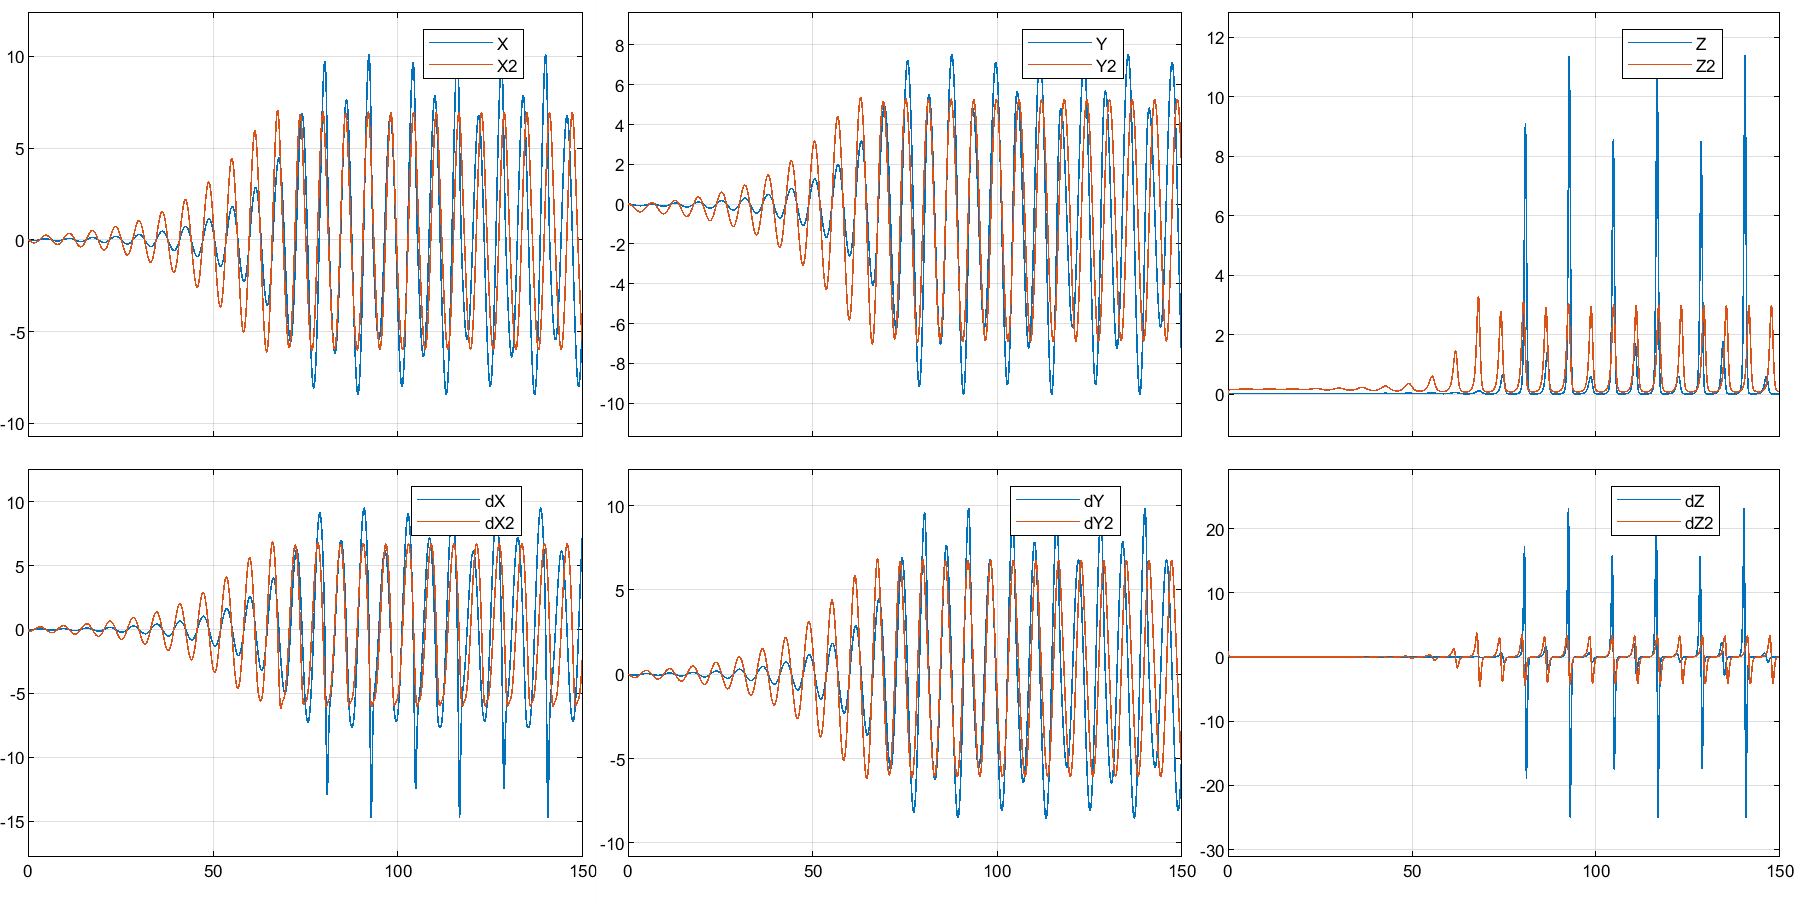

Parameterset 4: a = 0.15;  b = 0.2; *** c = 10***;

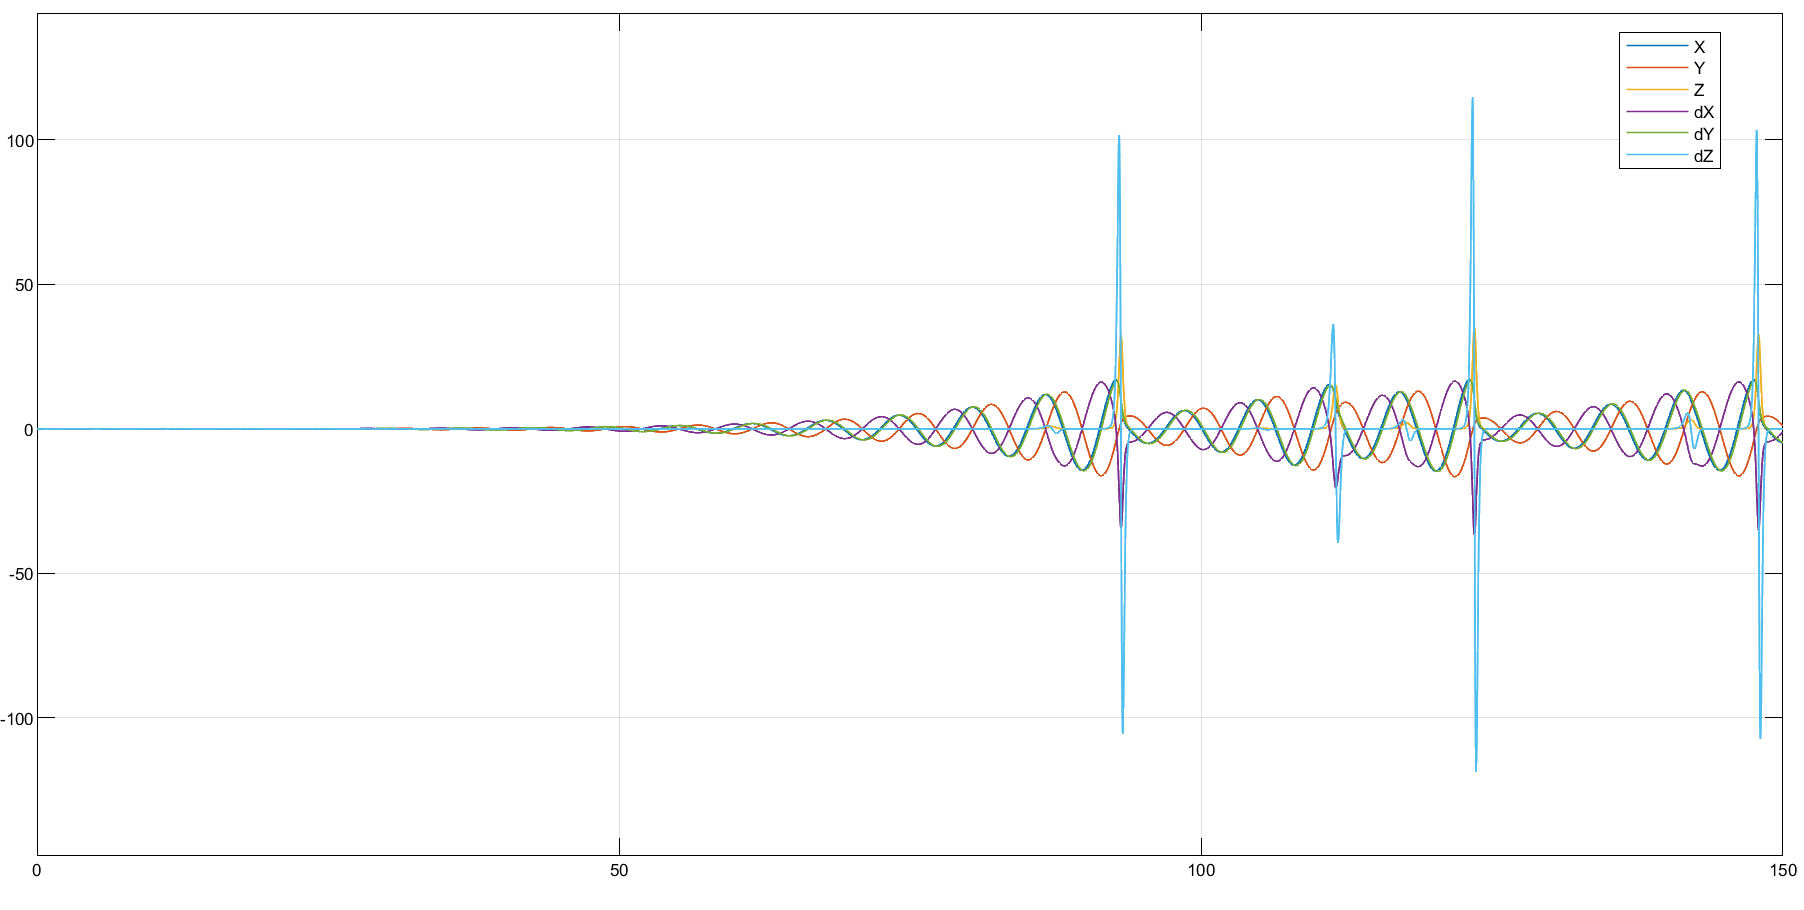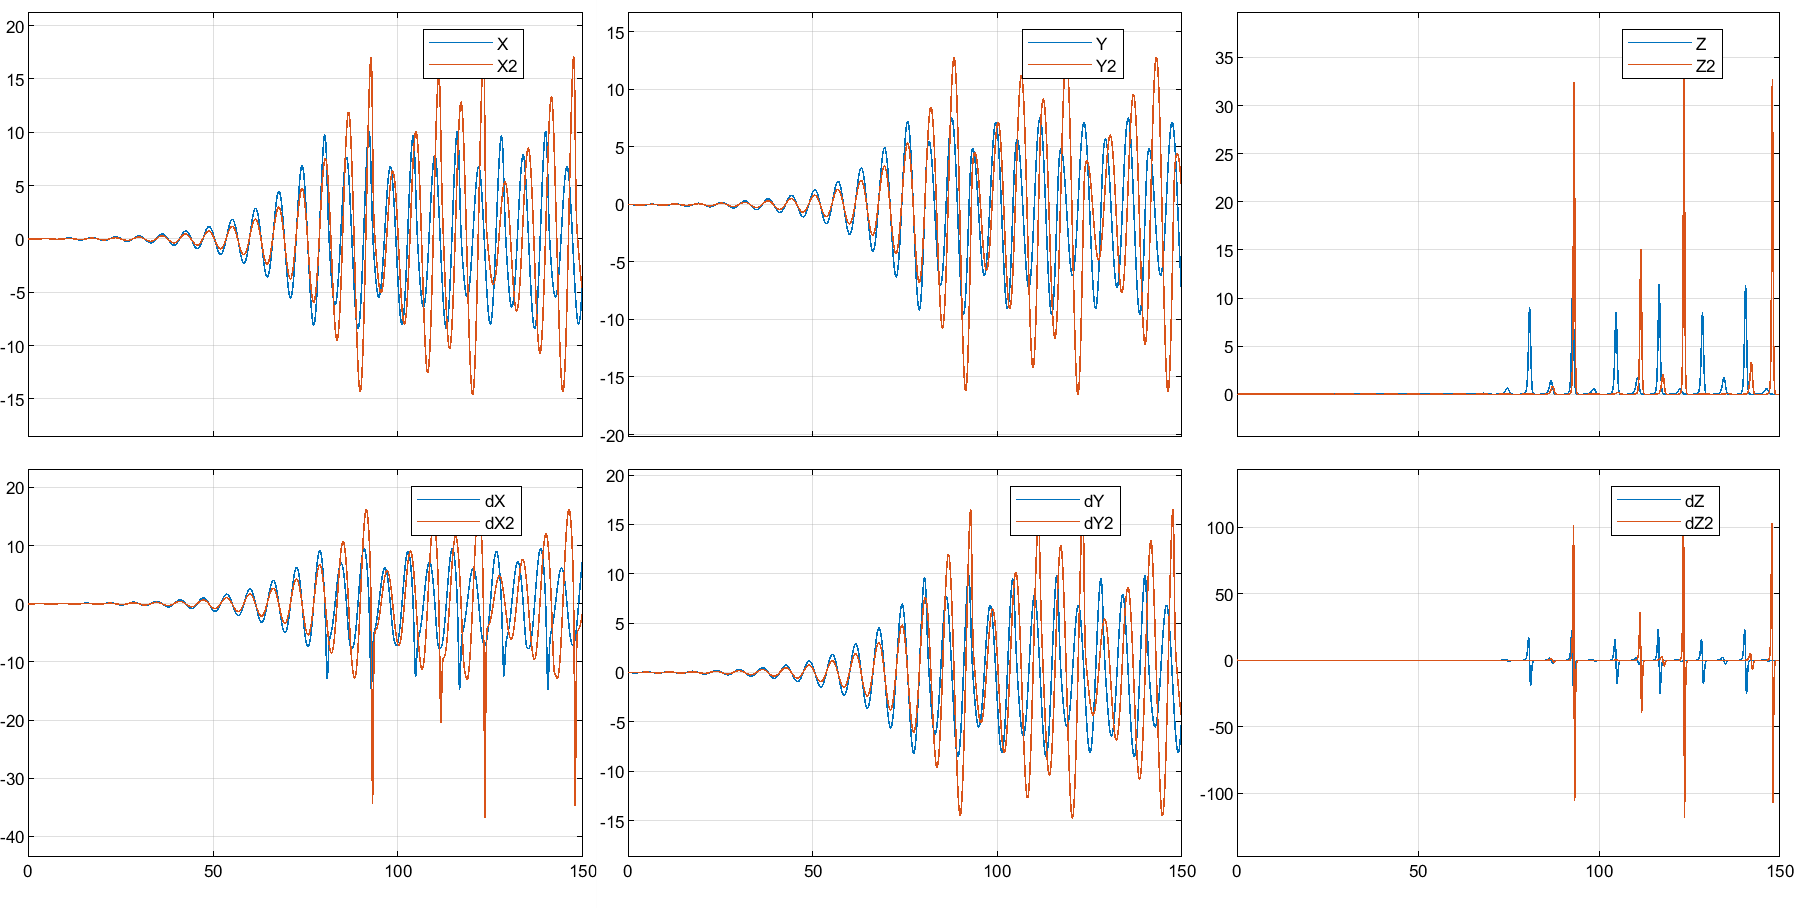

### *Schlussfolgerung : *

- *Eine Erhöhung der Parameter ****a ****und ****c**** führt zu einer Erhöhung auf ****X Y**** und ****Z, ****der Einfluss auf ****Z**** ist deutlich und offensichtlich *

- *Eine Erhöhung der Parameter ****b**** führt zu einer Reduzierung auf ****X Y**** und ****Z****, der Einfluss auf ****Z**** ist deutlich und offensichtlich *

- *Je höher ist ****a, ****desto chaotischer ist Rössler-Attraktor, wie das Bild aus Parameterset 2 gezeigt hat,**** Z ****läuft aperiodisch*

- *Je höher ist ****b****, desto flacher ist Rössler-Attraktor in 3D-Figur, da ****Z**** durch den Einfluss von ****b**** stark reduziert wurde*

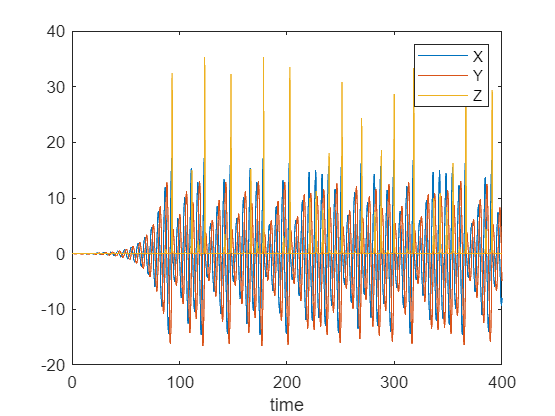

clc
close
clear
% name = 'Runqi Dong';

%Parameterset 1: a = 0.15;  b = 0.2;  c = 10;
a = 0.15;
b = 0.2;
c = 10;

%Parameterset 1: a = 0.2;  b = 0.2;  c = 8;
% a = 0.2;
% b = 0.15;
% c = 8;

% Aufgabe 2 wurde durch ode45 gelöscht, zuerst definiere ich eine Funktion f inklusive allen drei DGLs,
% dann stelle die Anfangsbedigungen für X, Y, Z und Simulationszeitbereich.
% Zum Schluss wird Rössler Attraktor sowohl in 2D als auch in 3D-Figur geplottet.

f = @(t,f) [-f(3) - f(2); f(1) + a*f(2) ; b + (f(1)-c)*f(3)];
y0 = [0,0,0];
[t,f] = ode45(f,[0 400],y0);     

% Plot in 2D-Figur
plot(t, f);
legend('X','Y','Z');
xlabel("time")

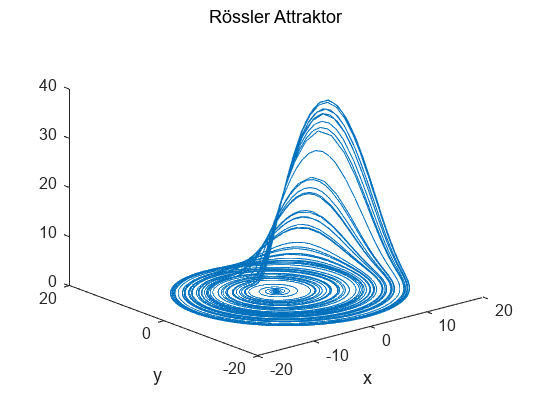


% Plot in 3D-Figur
figure;
plot3(f(:,1),f(:,2),f(:,3))
title("Rössler Attraktor")
xlabel("x")
ylabel("y")

view([-40 25])